# Rozwiązywanie równań różniczkowych

#### 27.11.2024, Mateusz Wójcik

Celem laboratorium było zapoznanie się z metodami numerycznego rozwiązywania ODE, czyli równań różniczkowych zwyczajnych z użyciem środowiska Matlab. Na wcześniejszych zajęciach korzystaliśmy z solverów takich równań w środowisku Simulink, natomiast na tych zajęciach zapoznamy się jak można je wykorzystać bezpośrednio w Matalbie.

clear, clc

## Metoda Eulera

Zanim zapoznano się z bardziej zaawansowanymi metodami, ćwiczeniowo zapoznano się z metodą Eulera oraz zaimplementowano ją. Jest to najprostsza metoda do rozwiązywania równań różniczkowych zwyczajnych. Metoda, ta w rzeczywistych realiach nie jest jednak wykorzystywana, ponieważ daje niedokładne wyniki i wiąże się z długim czasem wykonywania.

Kroki w metodzie Eulera są obliczane według następującego schematu:

$y_{n+1} = y_n + hf(t_n, y_n)
$,

$t_{n+1} = t_n + h
$,

gdzie $h$, to krok w metodzie Eulera.

## Zadanie 1

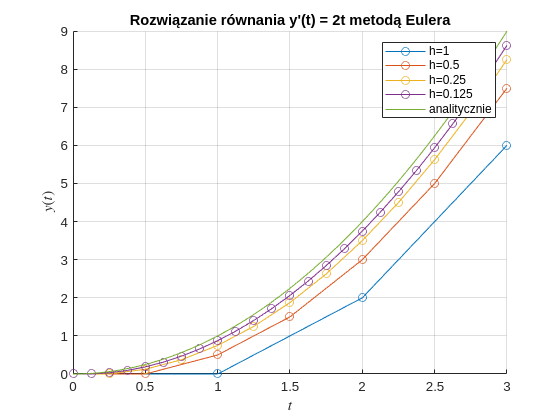

h = [1, 0.5, 0.25, 0.125];
legend_label = [];

figure();

hold on
for step = h
    x  = 0:step:3;
    y = zeros([1,length(x)]);
    
    for i = 2:(length(x))
        y(i) = y(i-1) + step*2*x(i-1);
    end
    plot(x,y, "o-")

    label_xy = "h="+ num2str(step);
    legend_label = [legend_label; label_xy];
end

% Wartość analityczna
fplot(@(t) t.^2, [0,3])
legend_label = [legend_label; "analitycznie"];

% Opisanie wykresu
title("Rozwiązanie równania y'(t) = 2t metodą Eulera")
ylabel("$y(t)$",Interpreter="latex")
xlabel("$t$",Interpreter="latex")
legend(legend_label, "AutoUpdate","on")
grid on

hold off

Jak można zauważyć na powyższym wykresie, odpowiednio zmniejszając krok, jesteśmy w stanie dostawać coraz dokładniejsze, przybliżenie funkcji, konsekwencją tego jest jednak wydłużony czas obliczeń.

## Przykład z wahadłem

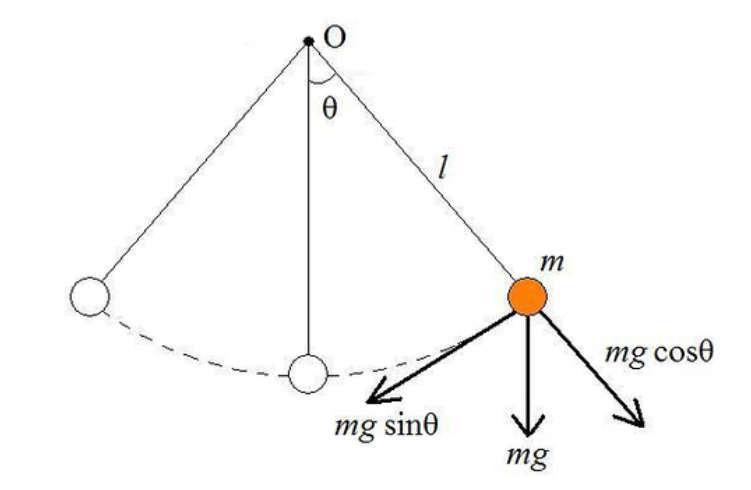

W celu zapoznania się z sposobem wykorzystania solverów wbudowanych w Matlaba rozważono prosty przykład wahadła, przedstawionego na rysunku powyżej oraz opisanego zmiennymi stanu:


$$\begin{cases} 
y_1 = \theta  \\
y_2 = \dot{\theta}
\end{cases}$$


,gdzie przechodząc do przestrzeni stanów otrzymano:


$$\begin{cases} 
\dot{y}_1 = y_2 \\ 
\dot{y}_2 = -\frac{b}{m} y_2 - \frac{mg}{L(m - 2b)} \sin(y_1)
\end{cases}$$


W tym celu stworzono odpowiednią funkcję:

function dy2dt2 = wahadlo(t,y)

g = 9.81;
L = 1;
m = 2;
b = 0.2;
dy2dt2 = [y(2); -b/m*y(2) - m*g/L/(m-2*b)*sin(y(1))];

end

A następnie wykorzystano solver ode45 w następującej konfiguracji:

opts = odeset('stats','on');
tspan = [0 25];
y0 = [pi/4, 0];
[t_w,y_w] = ode45(@wahadlo, tspan, y0, opts);

115 successful steps
0 failed attempts
691 function evaluations


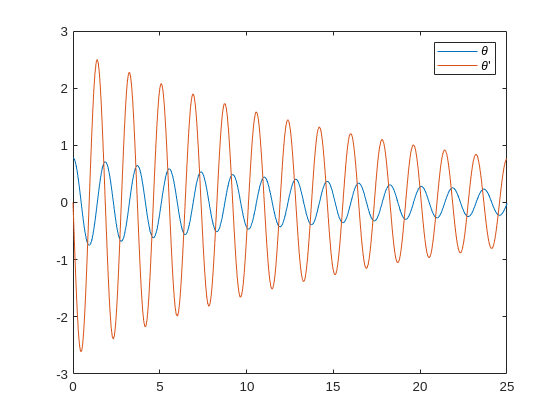

plot(t_w,y_w(:,1),t_w,y_w(:,2))
legend('\theta','\theta''')

W wyniku tego powstał wykres przedstawiający ruch drgający z tłumieniem.

## Zadanie 2

W drugim zadaniu, należało rozwiązać problem z pierwszego zadania, przy użyciu solvera ode45. Poniżej przedstawiono kod umożliwiający to:

tspan = [0,3];
y0 = 0;

#### Przekazanie funkcji do solvera ode45 można dokonać na kilka różnych sposobów:

**a) Funkcja zdefiniowana w osobym pliku vdp.m**

[T, Y] =ode45(@vdp, tspan,y0, opts);

10 successful steps
0 failed attempts
61 function evaluations


**b) Funkcja zdefiniowana w skrypcie:**

fun = @(t,y) 2*t;
[T1, Y1] = ode45(fun, tspan,y0, opts);

10 successful steps
0 failed attempts
61 function evaluations


**c) Wykorzystanie funkcji anonimowej:**

[T2, Y2] = ode45(@(t,y) 2*t, tspan, y0, opts);

10 successful steps
0 failed attempts
61 function evaluations


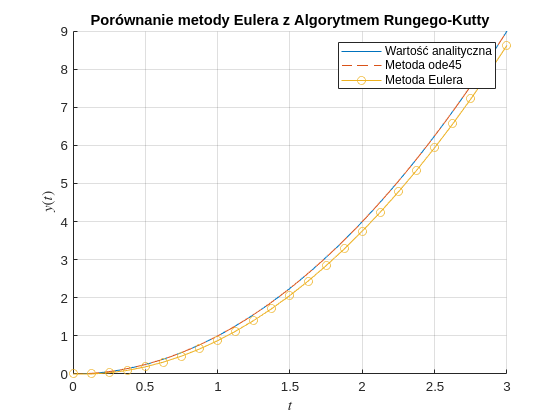

figure();
hold on
fplot(@(t) t.^2, [0,3])
plot(T,Y, "--");
plot(x,y,'o-');

title("Porównanie metody Eulera z Algorytmem Rungego-Kutty");
ylabel("$y(t)$",Interpreter="latex");
xlabel("$t$",Interpreter="latex");
legend(["Wartość analityczna","Metoda ode45", "Metoda Eulera"])
grid on

hold off

Na powyższym wykresie przedstawiono wyniki uzyskane przy wykorzystaniu solvera ode45, aplikującego algorytm Rungego-Kutty 4-tego i 5-tego rzędu, rozwiązanie metodą Eulera oraz wartość wyznaczoną analitycznie. Można zauważyć, że dla tego prostego przykładu widać już różnicę między metodą Eulera, a wartością analityczną. Natomiast algorytm Rungego-Kutty,  pokrywa się z rozwiązaniem analitycznym, nie pozwalając zaobserwować na wykresie żadnej wizualnej różnicy.

## Hamownik

Ostatnim etapem laboratorium było rozwiązanie problemu hamownika samolotu, przy pomocy poznanego solvera. W tym przypadku zdefiniowano dwie funkcje, jedną która w zmiennych stanu zawiera położenie i prędkość samolotu oraz drugą, która pozwala na wyliczenie przyspieszenia działającego na obiekt, po każdej iteracji solvera. Kod funkcji oraz wywołania przedstawiono poniżej:

### hamownik.m

function Dx = hamownik(t,x)

    h = 42;       %[m]
    m1=14000;     %kg
    m2=450.28;    %kg
    m3=200;     %kg
    K1=54.7;      %kN/m
    K2=303.6;     %kN/m
    k1 = K1 * 1000;
    k2 = K2 * 1000;
    
    % interpolacja
    wezlyF3 = [0 10 20 30 40 50 60 70 80 90 94 98 102 104 107 120];
    wartosciF3 = [833 400 160 320 520 520 660 830 1070 1600 2100 2800 4100 5000 9000 9000];
    funF3 = interp1(wezlyF3,wartosciF3,x(5),'pchip');
    Fb = funF3*x(6)^2;
    
    % zmienne stanu
    y1 = sqrt(x(1)^2 + h^2) - h;
    sin_theta = x(1)/sqrt(x(1)^2+h^2);
    
    if y1 >= 2*x(3)
        Fk1 = k1*(y1-2*x(3));
    else
        Fk1 = 0;
    end
    
    if x(3) >= x(5)
        Fk2 = k2*(x(3)-x(5));
    else
        Fk2 = 0;
    end
    
    dx(1) = x(2);
    dx(2) = -2*Fk1*sin_theta/m1;
    dx(3) = x(4);
    dx(4) = (2*Fk1-Fk2)/m2;
    dx(5) = x(6);
    dx(6) = (Fk2 - Fb)/m3;
    
    Dx = [dx(1);dx(2);dx(3);dx(4);dx(5);dx(6)];
end

#### hamownik_out.m

function status = hamownik_out(t,x,flag)

    global w3
    h = 42;       %[m]
    k1 = 54.7e3;  %[N/m]
    m1 = 14000;   %[kg]

    if strcmp(flag,'init')
    w3 = 0;
    elseif isempty(flag)
        y1 = sqrt(x(1)^2+h^2)-h;
        sin_theta = x(1)/(h+y1);

        if y1 >= 2*x(3)
            Fk1 = k1*(y1-2*x(3));
        else
            Fk1 = 0;
        end
        
        w3 = [w3;-2*Fk1*sin_theta/m1];
    end
    status = 0;
end

#### Kod wywołujący

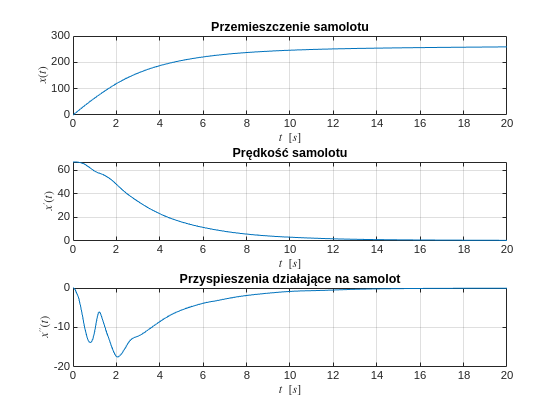

global w3;
options = odeset('OutputFcn',@hamownik_out,'Refine',1);
[Th,Yh] = ode45(@hamownik,[0 20],[0 67 0 0 0 0],options);

figure();

subplot(311);
plot(Th, Yh(:,1));
title("Przemieszczenie samolotu")
ylabel("$x(t)$",Interpreter="latex")
xlabel("$t \ [s]$", Interpreter="latex")
grid on

subplot(312);
plot(Th, Yh(:,2));
title("Prędkość samolotu")
ylabel("$x'(t)$",Interpreter="latex")
xlabel("$t \ [s]$", Interpreter="latex")
grid on

subplot(313);
plot(Th,w3);
title("Przyspieszenia działające na samolot")
ylabel("$x''(t)$",Interpreter="latex")
xlabel("$t \ [s]$", Interpreter="latex")
grid on

Dzięki temu uzyskano identyczne wyniki jak przy modelowaniu tego problemu za pomocą Simulinka. Pozwala to stwierdzić, że obie metody dają jednakowe rezultaty, przy zupełnie różnym podejściu do sposobu realizacji problemu (blokowo i funkcyjnie). Napewno ten sposób przedstawiania jest łatwiejszy, gdy przyjdzie nam naprawiać własne błędy, przy debugowaniu. Minusem jest mniejsza intuicyjność, nie widzimy jak "przepływa" sygnał oraz nie mamy bezpośredniego dostępu do np. przyspieszenia, da się to jednak rozwiązać stosując funkcję pomocnicze.

## Wnioski

W trakcie zajęć zapoznano się również z informacjami dotyczącymi innych solverów, których implementacje można odnaleźć w środowisku Matlab, są to m.in. 

- `ode233`

- `ode113`

- `ode15s`

- `ode23s`

- `ode23t`

- `ode23tb`

Każdy z tych solverów ma własne wyspecjalizowane zastosowania, które można uzyć w problemie o danej specyfice. Najważniejszym efektem zajęć w mojej opinii jest poznanie kolejnej metody modelowania obiektów dynamicznych. Metoda ta pozwala na bezpośrednie rozwiązywanie problemu, bez potrzeby dokonywania transformaty Laplace'a, rozwiązania problemu przy użyciu transmitancji i powrotu do dziedziny czasu. Oczywiście jak wszystko, to podejście ma również swoje wady, takie jak możliwa niestabilność wteczna zaimplementowanych algorytmów przy specyficznym problemie, popełnianie błędów zaokrągleń i tym podobnych. Napewno jednak, nie raz jeszcze wykorzystam ją, czy to podczas studiów, czy podczas kariery zawodowej.